clc
clear
imaqreset

cams = webcamlist

cams = 3×1 cell array
    {'Microsoft® LifeCam Cinema(TM)'}
    {'Snap Camera'                  }
    {'FaceTime HD Camera (Built-in)'}


cam = webcam(1);
img = snapshot(cam)

img = 720×1280×3 uint8 array
img(:,:,1) =

    51    51    51    51    51    51    51    51    53    55    56    57    55    55    55    58    61    62    59    58    57    57    57    58    57    55    54    53    51    50    49    50    55    57    58    58    59    60    61    62    59    59    59    59    60    60    61    58    53    51    51    51    51    51    52    52    54    54    55    58    59    60    61    62    61    59    58    59    59    60    61    63    65    64    62    61    60    60    59    58    62    61    59    58    56    55    54    53    54    55    56    57    58    58    58    57    58    57    58    59    59    58    59    59    59    59    60    62    63    65    66    65    66    65    63    61    61    62    63    63    66    65    63    62    61    61    60    60    68    59    48    42    40    41    47    52    57    61    77    98   110   107   102   101    91    87    85    82    79    76    73    71    81    82    85    89    91    93    93   

load img_color.mat

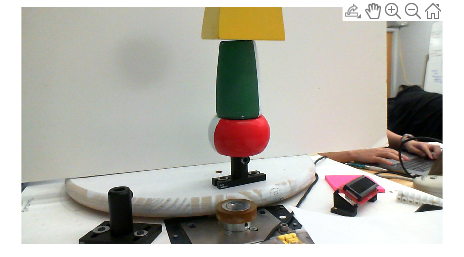

imshow(img)

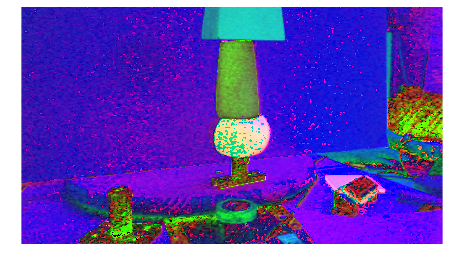

hsv_img = rgb2hsv(img);
h = hsv_img(:,:,1);
s = hsv_img(:,:,2);
v = hsv_img(:,:,3);
imshow(hsv_img);

figure;
subplot(1,3,1);
imshow(h);
subplot(1,3,2);
imshow(s);
subplot(1,3,3);
imshow(v);

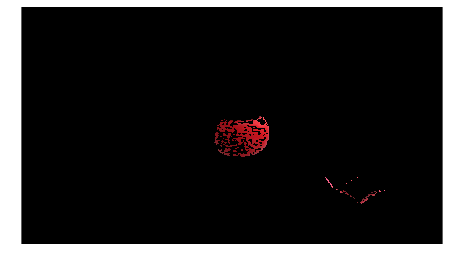

lower_red = [170,150,100];
upper_red = [255,255,255];
red_mask = mask_img(hsv_img,lower_red,upper_red);
red_masked = red_mask.*hsv_img;
red_res = hsv2rgb(red_masked);
figure()
imshow(red_res)

lower_yellow = [20,100,100];
upper_yellow = [80,255,255];
yellow_mask = mask_img(hsv_img,lower_yellow,upper_yellow);
yellow_masked = yellow_mask.*hsv_img;
yellow_res = hsv2rgb(yellow_masked);
figure()
imshow(yellow_res)

lower_green = [80,80,50];
upper_green = [150,180,180];
green_mask = mask_img(hsv_img,lower_green,upper_green);
green_masked = green_mask.*hsv_img;
green_res = hsv2rgb(green_masked);
largest_green = smooth_image(green_mask);
imshow(largest_green)
% imshow(green_mask)
% imshow(largest_green)

largest_red = smooth_image(red_mask);
largest_green = smooth_image(green_mask);
largest_yellow = smooth_image(yellow_mask);

[rb, hr] = find_contour(largest_red,'red');
[yb, hb] = find_contour(largest_yellow,'yellow');
[gb, hg] = find_contour(largest_green,'green');

bounds = {rb;yb;gb};
colors = ['r' 'y' 'g']
texts = ['red','yellow','green'];
h = [hr;hb;hg];
figure()
imshow(img);
hold on
for i=1:3
    boundary = cell2mat(bounds(i));
    plot(boundary(:,2), boundary(:,1),colors(i),'LineWidth',2);
    set(h(i),'Color',colors(i),'FontSize',14,'FontWeight','bold');
end
hold off



[B,L,N,A] = bwboundaries(largest_red);
imshow(img); 
hold on;
colors=['r' 'g' 'y'];
for k=1:length(B),
  boundary = B{k};
  cidx = mod(k,length(colors));
  plot(boundary(:,2), boundary(:,1),...
       colors(cidx),'LineWidth',2);

  %randomize text position for better visibility
  rndRow = ceil(length(boundary)/(mod(rand*k,7)+1));
  col = boundary(rndRow,2); row = boundary(rndRow,1);
  h = text(col+1, row-1, 'red');
  set(h,'Color',colors(cidx),'FontSize',14,'FontWeight','bold');

end



function [boundary, h] = find_contour(area_img,txt)
    B = bwboundaries(area_img);
    boundary = B{1};
    rndRow = length(boundary);
    col = boundary(rndRow,2);
    row = boundary(rndRow,1);
    h = text(col+1, row-1,txt);
end

function mask = mask_img(hsv_img,lower,upper)
    lower = lower/256;
    upper = upper/256;
    h = hsv_img(:,:,1);
    s = hsv_img(:,:,2);
    v = hsv_img(:,:,3);
    h_mask = h >= lower(1) & h <= upper(1);
    s_mask = s >= lower(2) & s <= upper(2);
    v_mask = v >= lower(3) & v <= upper(3);
    mask = h_mask & s_mask & v_mask;
end

function largest_area = smooth_image(mask)
    %dilation
    se = strel('square',5);
    smooth = imdilate(mask,se);
    imshow(smooth);
    im_fill = imfill(smooth, 'holes');

    % remove parts that are smaller than 500 pixels
    filtered = bwareaopen(im_fill,500);
%     imshow(filtered);
    % find largest area
    s = regionprops(filtered, 'Area', 'PixelList');
    
    [~,idx] = max([s.Area]);

    Indices = s(idx).PixelList;
    largest_area = false(size(filtered));
 
    for i = 1:length(Indices)

        largest_area(Indices(i,2),Indices(i,1)) = 1;
    end
    
    
end